**Exercise 4 ECE537 **

**Julie Jiang V00902597**

**Zixuan Deng V00971633**

**Exercise 2 ECE537 **

**Julie Jiang V00902597**

**Zixuan Deng V00971633**

**Table of Contents**

1. Load the Exercise 4 data set. This data comprises 1000 samples from 2 classes in 100 measurement dimensions.
2. Comment on whether the available data represents a dense sampling of this high dimensional space and, if you assumed both data classes were Gaussian distributed, then discuss how many data samples would be required to provide a sufficient dense sampling of the data across all of its dimensions.
3. Randomly partition the data into training and test sets where the train-ing set represents 25% of the data and the test set represents the re-maining 75% of the data.
4. Use the training data to construct a Principal Component Analysis (PCA) approach to reduce the data to 3 dimensions and apply this dimensionality reduction to the test data.
5. Apply Bayes classification on the dimensionality reduced test data and comment on the classification performance.
6. Discuss whether PCA is a correct approach to apply for addressing classification problems and present clear arguments as to why (or why not).
7. Use the training data to construct a Fisher Linear Discriminant and use the learned discriminant to reduce the test data to one dimension.
8. Apply Bayes classification on the dimensionality reduced test data and comment on the classification performance.
9. Discuss the characteristics of the resulting dimensionality reduction vector and the Fisher-based approach was able to classify the data versus the results obtained for the PCA-based approach.
10. Discuss whether the performance of PCA would have improved if a higher percentage of the data was used in training the PCA system.
 11. Use Matlab's neural network toolbox to train a neural network on the original data set, while using a randomly selected 25% of the data as the training and the remaining data as the test data.
12. Discuss the resulting neural network’s ability to correctly classify this data set, in comparison to the results produced under PCA and Fisher and, in particular, the differences and distinctions between the knowledge gained about the problem domains between the neural network and Fisher approaches and whether this would continue to hold for non-linearly separable problem domains. 
13. Now remove the feature vector identified through the Fisher analysis and retrain a new neural network based on this data. Discuss the classification performance that this classifier achieves and the overall distribution of classification performances that such a classifier could be seen to achieve. 
14. Discuss whether it would be common in operational data analysis settings for dense data samplings to be available a priori from which analytics systems could then be trained or whether this is more likely to occur rarely. Discuss the implications this has one training data analytics systems and, particularly, the selection of measurement features based on the analyses of available data.

### **1. Load the Exercise 4 data set. This data comprises 1000 samples from 2 classes in 100 measurement dimensions.**

After loading the dataset, we find dataset "a" is the one contains 1000 samples in 100 measurement dimensions. And dataset "classes" is indicator label to classify the two classes. 

clear all;
clear cfg;
% Load the Exercise 4 data set. 
load ('Exercise_4_Data.mat');

a

a = 	1.0e+09 *

    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   

classes

classes =      0     1     0     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     0     1     1     1     1     0     1     1     0     1     1     1     0     0     0     1     1     1     0     1     1     1     1     1     0     0


### **2. Comment on whether the available data represents a dense sampling of this high dimensional space and, if you assumed both data classes were Gaussian distributed, then discuss how many data samples would be required to provide a sufficient dense sampling of the data across all of its dimensions.**

The available data does not represents the a dense sampling of this high dimensional space. As the data sample is 1000 with 100 dimensions. If assumed both data classes were Gaussian distributed, it would require $2^{100}$data samples to provide a sufficient dense sampling of the data across all of its dimensions. 

### 3. Randomly partition the data into training and test sets where the train-ing set represents 25% of the data and the test set represents the re-maining 75% of the data.

% 25 percent of data used for training
training_data = a(Train_indx, :);
training_label = classes(Train_indx);

% 75 percent of data used for testing
testing_data = a(Test_indx, :);
testing_label = classes(Test_indx);

### 4. Use the training data to construct a Principal Component Analysis (PCA) approach to reduce the data to 3 dimensions and apply this dimensionality reduction to the test data.

training_data_pca = PCA(training_data, training_data - mean(training_data), 3)

training_data_pca = 	1.0e+08 *

   -0.4302   -0.0000    0.0000
    5.9965    0.0000    0.0000
    2.3370   -0.0000    0.0000
   -1.8693   -0.0000   -0.0000
   -3.2629   -0.0000   -0.0000
   -5.2928   -0.0000    0.0000
   -5.7013    0.0000   -0.0000
   -1.6627    0.0000    0.0000
    0.3301    0.0000    0.0000
    5.3908   -0.0000   -0.0000


testing_data_pca = PCA(training_data, testing_data - mean(testing_data), 3)

testing_data_pca = 	1.0e+09 *

   -0.2623    0.0000    0.0000
   -0.2163   -0.0000   -0.0000
   -0.8384    0.0000   -0.0000
    0.0919   -0.0000    0.0000
    0.2210   -0.0000    0.0000
    0.6072    0.0000   -0.0000
   -0.0044    0.0000   -0.0000
   -0.0132    0.0000    0.0000
    0.2934   -0.0000    0.0000
   -0.0715   -0.0000    0.0000


### 5. Apply Bayes classification on the dimensionality reduced test data and comment on the classification performance.

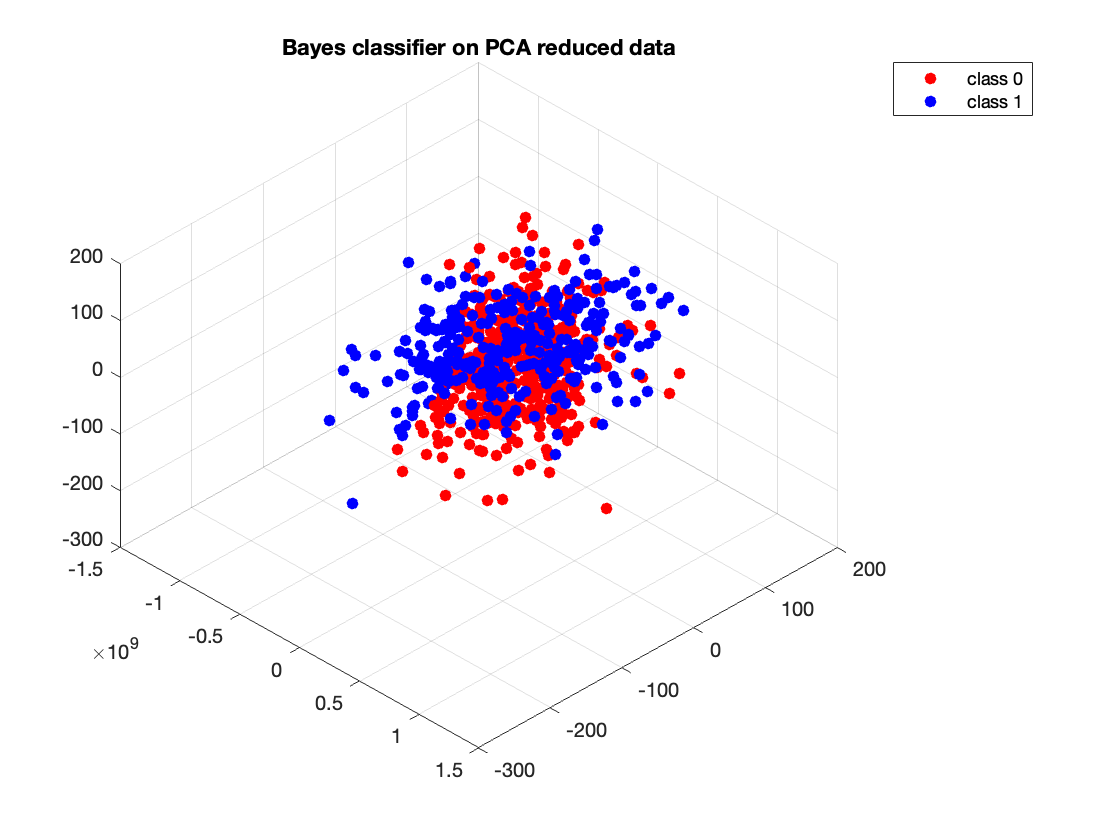

training_class_0 = training_data_pca(training_label == 0, : );
training_class_1 = training_data_pca(training_label== 1, : );
testing_class_0 = testing_data_pca(testing_label == 0, : );
testing_class_1 = testing_data_pca(testing_label== 1, : );

% Calculate mean and covariance for classes 0 and 1
mean_0 = mean(training_class_0);
mean_1 = mean(training_class_1);

cov_0 = cov(training_class_0);
cov_1 = cov(training_class_1);

% Calculate the a priori probability for each class in training data set
prior_0 =length(training_class_0) / length(training_class_0);
prior_1 = length(training_class_1) / length(training_class_1);

% should we use mean and covariance from testing dataset???
[class_0, class_1]=classifier(testing_data_pca, mean_0,cov_0,prior_0,mean_1,cov_1,prior_1);

% data that predicted as class 0 and 1 
predict_0 = testing_data_pca(class_0, :);
predict_1 = testing_data_pca(class_1, :);

% Plot the classes 0, 1 regions
scatter3(predict_0(:, 1), predict_0(:, 2), predict_0(:, 3), 'filled', 'red')
hold on;
scatter3(predict_1(:, 1), predict_1(:, 2), predict_1(:, 3), 'filled', 'blue')
title('Bayes classifier on PCA reduced data')
legend('class 0', 'class 1')
view([45, 45]);
hold off;



% Need to test the performance
accuracy = Performance(testing_data_pca,class_0, class_1, testing_label)

accuracy = 0.4960

### 6. Discuss whether PCA is a correct approach to apply for addressing classification problems and present clear arguments as to why (or why not).

PCA is not a correct approach to apply for addressing classification problems, because PCA is a technique to reduce dimension for data, it capture the data that has most variation (has the most information). However, it does not actually do a classification.  Classification like Bayes classification, the result will be data that predicted to one class. But PCA does not do that. 

### 7. Use the training data to construct a Fisher Linear Discriminant and use the learned discriminant to reduce the test data to one dimension.

- Group the training data into it’s respective classes .

- Calculate mean vector of given training data of K-dimensions excluding the target class and also calculate class-wise mean vector for the given training data.

- Calculate SB and SW matrices needed to maximize the difference between means of given classes and minimize the variance of given classes.

- After that calculate the matrix M , where M = (inv(SW)).(SB)

- Calculate eigen values of M and get eigen vector pairs for first n (needed ) dimensions.

- This eigen vectors give us the value of ‘w’ used to transform points to needed number of dimensions.

training_data_0 = training_data(training_label == 0, : );
training_data_1 = training_data(training_label == 1, : );


testing_data_0 = testing_data(testing_label == 0, : );
testing_data_1 = testing_data(testing_label == 1, : );


mean_class_0 = mean(training_data_0);
mean_class_1 = mean(training_data_1);

% Calculate Sb (between-class covariance matrix)
Sb = (mean_class_0' - mean_class_1') * (mean_class_0' - mean_class_1')'

Sb = 	1.0e+14 *

    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000  




Sw_0 = (training_data_0' - mean_class_0') * (training_data_0' - mean_class_0')';
Sw_1 = (training_data_1' - mean_class_1') * (training_data_1' - mean_class_1')';


Sw = Sw_0 + Sw_1

Sw = 	1.0e+19 *

    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000  



w = Sw\eye(size(Sw))*(mean_class_0'-mean_class_1');

w = inv(Sw)*Sb

w = 	1.0e+17 *

    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   

fisher_training_data = training_data * w(:,1);

% get transformed fisher data
fisher_testing_data= testing_data * w(:,1);


### 8. Apply Bayes classification on the dimensionality reduced test data and comment on the classification performance.

training_fisher_class_0 = fisher_training_data(training_label == 0, : );
training_fisher_class_1 = fisher_training_data(training_label== 1, : );
testing_fisher_class_0 = fisher_testing_data(testing_label == 0, : );
testing_fisher_class_1 = fisher_testing_data(testing_label== 1, : );

% Calculate mean and covariance for classes 0 and 1
mean_0_fisher = mean(training_fisher_class_0);
mean_1_fisher = mean(training_fisher_class_1);

cov_0_fisher = cov(training_fisher_class_0)

cov_0_fisher = 3.1757

cov_1_fisher = cov(training_fisher_class_1)

cov_1_fisher = 2.1688


% should we use mean and covariance from testing dataset???
p0 = length(training_fisher_class_0) / length(fisher_training_data)

p0 = 0.5600

p1 = length(training_fisher_class_1) / length(fisher_training_data)

p1 = 0.4400


% d_f = @(x, mu, sigma) -0.5*((x - mu).^2)/sigma;
d_f = @(x, mu, sigma,p) -0.5*((x - mu).^2)/sigma - 1/2*log(abs(sigma)) + log(p);
gk_a = d_f(fisher_testing_data,mean_0_fisher, cov_0_fisher,p0);
gk_b = d_f(fisher_testing_data,mean_1_fisher, cov_1_fisher,p1);


class_0_fisher = find(gk_a> gk_b);
class_1_fisher = find(gk_b>= gk_a);




% data that predicted as class 0 and 1 
predict_0_fisher = fisher_testing_data(class_0_fisher, :)

predict_0_fisher = 	1.0e+12 *

   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357


predict_1_fisher = fisher_testing_data(class_1_fisher, :)

predict_1_fisher = 	1.0e+12 *

   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357
   -1.0357


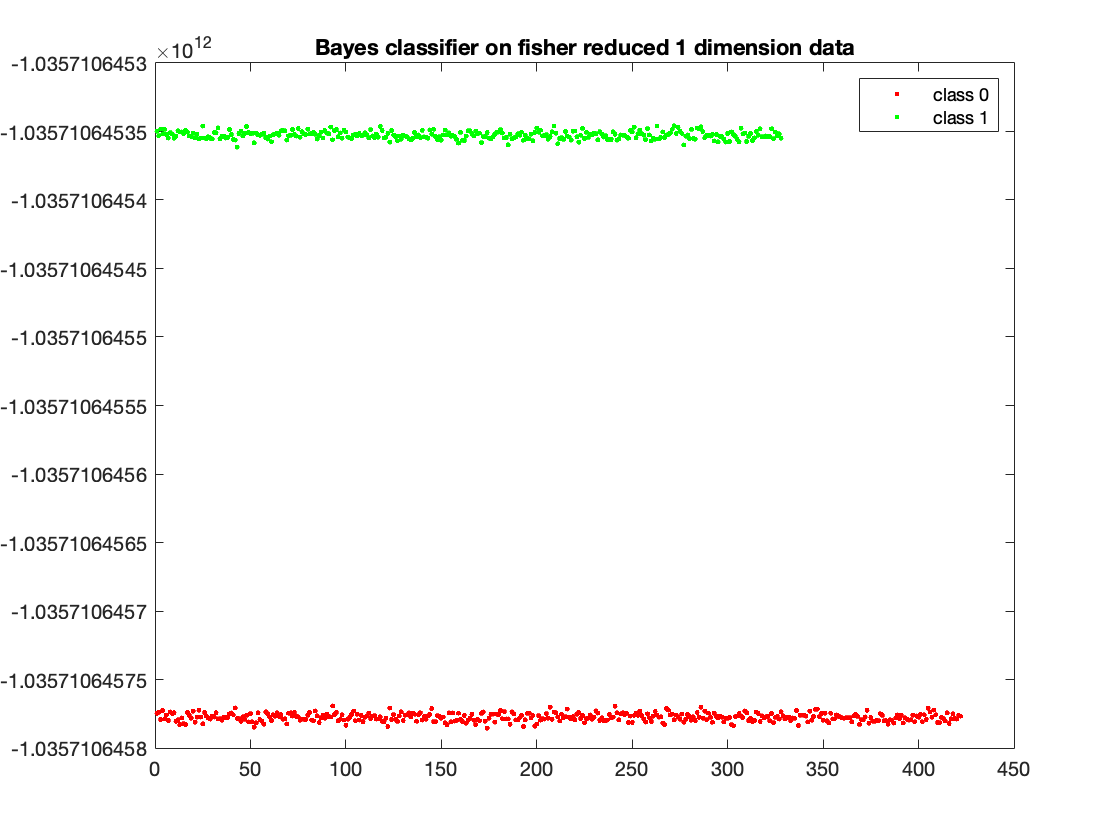


% Plot the classes 0, 1 regions
plot(predict_0_fisher,'.red')
hold on;
plot(predict_1_fisher,'.green')
title('Bayes classifier on fisher reduced 1 dimension data')
legend('class 0', 'class 1')
hold off;


% Measure performance of bayes classification based on fisher data
fisher_accuracy = Performance(fisher_testing_data,class_0_fisher, class_1_fisher, testing_label)

fisher_accuracy = 1

After apply Fisher Linear Discriminant, the bayes classification performs well on the classification. Fisher Linear Discriminant actually provide separation information that helps for classification. The dimensionality reduced data has the following properties: 

- minimize withinn classes covaraince

- maximize between classes covariance

Thus, the dimensionality reduced data has already have clear separatable space between two classes dataset. And this makes classifictaion performance good. 

### 9. Discuss the characteristics of the resulting dimensionality reduction vector and the Fisher-based approach was able to classify the data versus the results obtained for the PCA-based approach.

The resulting dimensionality reduction vector on PCA only remain the data that gives most information, it does not have anything that could help classification. Therefore, Bayes Classifier does not perform well on PCA reduced data set. 

Fisher Linear Discriminant actually provide separation information that helps for classification. The dimensionality reduced data has the following properties: 

- minimize withinn classes covaraince

- maximize between classes covariance

Meanwhile, PCA and Fisher-based approach can both do dimension reduction, and both are following a linear reducetion. But Fisher-based approach does help classification, PCA does not.  

### 10. Discuss whether the performance of PCA would have improved if a higher percentage of the data was used in training the PCA system.

The performance of PCA would not improved even if a higher percentage of the data was used in training the PCA system. PCA are used to do dimension reduction, but it does not provide anything useful to the classification. And based on the experiments we did, they also prove our conclusion. 

###  11. Use Matlab's neural network toolbox to train a neural network on the original data set, while using a randomly selected 25% of the data as the training and the remaining data as the test data.

training_data = a(Train_indx, :);
training_label = classes(Train_indx);

testing_data = a(Test_indx, :);
testing_label = classes(Test_indx);

data = [training_data; testing_data]

data = 	1.0e+09 *

    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000

Targets = [training_label testing_label]

Targets =      0     1     0     1     1     1     1     1     1     1     1     0     0     1     1     1     0     0     1     1     1     1     0     1     1     1     0     1     1     0     0     1     1     1     0     0     1     1     1     1     1     1     0     0     0     1     1     0     1     0



x = data';
t = Targets;

trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 25/100;
%net.divideParam.testRatio = 75/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x)

y =     0.0000    1.0000    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.0000    0.0000    1.0000    1.0000    1.0000    0.0000    0.0000    1.0000    1.0000    1.0000    1.0000    0.0000    1.0000    1.0000    1.0000    0.0000    1.0000    1.0000    0.0000    0.0000    1.0000    1.0000    1.0000    0.0000    0.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.0000    0.0000    0.0000    1.0000    1.0000    0.0000    1.0000    0.0000


e = gsubtract(t,y)

e = 	1.0e+-5 *

   -0.0125    0.0109   -0.0174    0.0127    0.0121    0.0079    0.0066    0.0096    0.0398    0.0285    0.0495   -0.0266   -0.0175    0.0092    0.0137    0.0222   -0.0181   -0.0345    0.0094    0.0256    0.0311    0.0466   -0.0133    0.0096    0.0217    0.0362   -0.0176    0.0187    0.0180   -0.0206   -0.0233    0.0146    0.0288    0.0552   -0.0190   -0.0151    0.0114    0.0176    0.0133    0.0160    0.0210    0.0205   -0.0197   -0.0157   -0.0263    0.0090    0.0119   -0.0157    0.0220   -0.0392


performance = perform(net,t,y)

performance = 2.3151e-07

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0


% View the Network
%view(net)

### 12. **Discuss the resulting neural network’s ability to correctly classify this data set, in comparison to the results produced under PCA and Fisher and, in particular, the differences and distinctions between the knowledge gained about the problem domains between the neural network and Fisher approaches and whether this would continue to hold for non-linearly separable problem domains. **

outputs=net(testing_data');
result = outputs';
epsilon = 1e-4;
% I guess Matlab has some error when direct compare float and int. 
class_0 = find(abs(result - 0) < epsilon);
class_1 = find(abs(result - 1) < epsilon);
matrix_1 = 2 * ones(1,length(result))';
matrix_1(class_0, :) = 0; 
matrix_1(class_1, :) = 1;
result_label = matrix_1; 

wrong_classification = sum(testing_label' ~= result_label)

wrong_classification = 0

Depend on the accuracy we got, we found the performace of NN and Fisher is better than PCA, and we found Fisher and NN has the similiar accuracy here. The NN is support for non-linear separation which PCA and Fisher are not support.  Fisher can tell us the dimenision we can use but NN not. PCA is failed since it does not provide any information for classification, but capture the data that contains most information. Therefore, performance is Fisher > = NN > PCA.

### 13. **Now remove the feature vector identified through the Fisher analysis and retrain a new neural network based on this data. Discuss the classification performance that this classifier achieves and the overall distribution of classification performances that such a classifier could be seen to achieve. **

[e, v] = eigs(inv(Sw) * Sb, 100);


[max_value, index] = max(abs(e));

data_matrix = a;
data_matrix(:, index) = [];

training_data2 = data_matrix(Train_indx, :);
testing_data2 = data_matrix(Test_indx, :);

testing_label2 = classes(Test_indx);
training_label2 = classes(Train_indx);
Targets2 = [training_label, testing_label];

data2 = [training_data2; testing_data2]

data2 = 	1.0e+09 *

    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.000


x = data2';
t = Targets2;

trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net2 = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net2.divideParam.trainRatio = 25/100;
net2.divideParam.testRatio = 75/100;

% Train the Network
[net2,tr] = train(net2,x,t);

% Test the Network
y = net2(x)

y =     0.5211    0.6713    0.4444    0.4202    0.5939    0.4537    0.5405    0.5038    0.5545    0.5083    0.4111    0.4855    0.2424    0.7006    0.7418    0.2391    0.7483    0.7083    0.6205    0.4512    0.4129    0.5673    0.3732    0.7685    0.5844    0.5026    0.5565    0.4116    0.4844    0.4502    0.4906    0.5011    0.5769    0.4011    0.4530    0.3880    0.3182    0.5814    0.6234    0.3840    0.7231    0.5574    0.6129    0.3181    0.5708    0.6924    0.6717    0.5059    0.6650    0.5206


e = gsubtract(t,y)

e =    -0.5211    0.3287   -0.4444    0.5798    0.4061    0.5463    0.4595    0.4962    0.4455    0.4917    0.5889   -0.4855   -0.2424    0.2994    0.2582    0.7609   -0.7483   -0.7083    0.3795    0.5488    0.5871    0.4327   -0.3732    0.2315    0.4156    0.4974   -0.5565    0.5884    0.5156   -0.4502   -0.4906    0.4989    0.4231    0.5989   -0.4530   -0.3880    0.6818    0.4186    0.3766    0.6160    0.2769    0.4426   -0.6129   -0.3181   -0.5708    0.3076    0.3283   -0.5059    0.3350   -0.5206


performance2 = perform(net2,t,y)

performance2 = 0.6725

tind = vec2ind(t);
yind = vec2ind(y);
% percentErrors = sum(tind ~= yind)/numel(tind)

% View the Network
%view(net2)

outputs=net2(testing_data2');
result = outputs';
epsilon = 1e-4;
class_0 = find(abs(result - 0) < epsilon);
class_1 = find(abs(result - 1) < epsilon);
matrix_1 = 2 * ones(1,length(result))';
matrix_1(class_0, :) = 0; 
matrix_1(class_1, :) = 1;
result_label = matrix_1; 


wrong_classification = sum(testing_label2' ~= result_label)

wrong_classification = 750

performance2

performance2 = 0.6725

performance

performance = 2.3151e-07

Compare the two NN, we can find after remove the feature vector, the different of predict is become huge, which means the error of the NN is more larger. This is because the removed feature vector contains critical information for classification. The rest 99 feature vectors are not as important as this removed one when do classification. And as this feature vector contains critical informtaion for classification, we can use fisher liner analysis to reduce data dimension to 1 and still get good classification result. 

### **14. Discuss whether it would be common in operational data analysis settings for dense data samplings to be available a priori from which analytics systems could then be trained or whether this is more likely to occur rarely. Discuss the implications this has one training data analytics systems and, particularly, the selection of measurement features based on the analyses of available data.**

We believe the dense data samplings is rarely happens. In our execrise, data's dimension can be reduced since there are many dimensions not contain information for classification. Otherwise, we may need 2^100(2 class) data points for dense data sampling. However, in industry, most likely the data has little or no prior information, therefore we require as much data as possible in most case. 

If we have 2 class, with large data dimension and sampling, we cannot reduce the dimension if all of the feature is important. But if some features are not important, we can use dimension reduction, and this will help to have less data sampling require in operational data analysis. 

function pca_data = PCA(train_data,test_data, n)
% input --> original data need to construct a PCA to reduce to n dimensions
% output --> decomposition data

data_centered = train_data - mean(train_data);
data_cov = cov(data_centered);
% e-> eigenvalues, v-> eigenvectors
[e,v] = eig(data_cov);
% sort eignvector descending. 
[ ~ , idx_eig ] = sort( diag(v) , 'descend' );
idx_remain = idx_eig( 1 : n );
sorted_eigenvector = e(: , idx_remain);
pca_data = test_data * sorted_eigenvector;

end

Function for Q5

% I have modified little bit the functions from A2 to fit the questions. 


function [class_a, class_b]=classifier(data, mua,cova,priora,mub,covb,priorb)
% return bayes classification result for class a or b. 
gk_a = discriment_f(data,priora, mua, cova);
gk_b = discriment_f(data,priorb, mub, covb);

class_a = find(gk_a> gk_b);
class_b = find(gk_b>= gk_a);
end


function g_x = discriment_f(x,prior_prob, mu, sigma)
% discriment function follows from equation 67 in Ch2.
    % use sigma\eye(size(sigma)) to subtitue inv(sigma) to improve
    % numericial 
    W_i = (-1/2)*inv(sigma);
    w_i = inv(sigma)*mu';
    w_i_0 = (-1/2)*mu*inv(sigma)*mu' - (1/2)*log(det(sigma))+log(prior_prob);
    g_x = sum((x*W_i.').*x,2).'+w_i'*x'+w_i_0;
    g_x = g_x.';

end




function accuracy = Performance(data,class_0_label, class_1_label, data_label)

label = 2 * ones(1,length(data))';
label(class_0_label, :) = 0;
label(class_1_label, :) = 1;
result_label = label;

% Calculate the performance of Bayes calssifier based on PCA
wrong_classifications = sum(result_label ~= data_label');
accuracy = 1 - wrong_classifications/length(data);
end